# Fringe Removal Algorithm

*Reference*:  Bo Song, Chengdong He, Zejian Ren, Entong Zhao, Jeongwon Lee, and Gyu-Boong Jo, Effective statistical fringe removal algorithm for high-sensitivity imaging of ultracold atoms, arXiv:2002.10053. Please kindly cite this reference if it helps you get rid of annoying fringes :)

*Authors*:  Created by Bo in 2018 and Updated by Chengdong and Entong

*Copyright*:  Ultracold Atom Lab at Hong Kong Univerisity of Science and Technology

*Update Date*:  23 August 2020

## **Data preparation**

Folder = 'Example';                         % image folder, an exmaple where absorption images have fringe patterns
                                            % intentionally induced to elaborate the fringe removal protocol.
BinFolder=[Folder,'_Temp'];                 % Temp folder is used to store converted Bin (basic binary) files.                       
if ~exist(BinFolder,'dir')
    mkdir(BinFolder);                       % reading and writing bin files are faster.
else
    delete([BinFolder,fs,'*'])              % clear Temp folder.
end
[imgHeightRaw,imgWidthRaw] = Txt2Bin(Folder, BinFolder); % convert Text (.data) or TIF into Bin file.

ResultFolder = [Folder,'_Result'];          % result foder
if ~exist(ResultFolder,'dir')
    mkdir(ResultFolder);                    
else
    rmdir(ResultFolder,'s')                 % clear Result folder.
end
fs = filesep;                               % file seperator for current platfrom
mkdir([ResultFolder,fs,'NewWO']);           %  -corrected Reference images. 
mkdir([ResultFolder,fs,'NewOD']);           %  -corrected OD images.
mkdir([ResultFolder,fs,'CmpImg']);          %  -comparison between images with/without fringe removal.
mkdir([ResultFolder,fs,'AvgOD']);           %  -average OD images.

## Fringe Removal Process

SumOD = 0;                                  % sum of corrected OD (with finge removal).
SumODorg = 0;                               % sum of orginal OD (without fringe removal).
filelistWO = dir([BinFolder,fs,'*WO.bin']); % find the file with suffix WO.bin. number of images in every folder assumed to be the same.
nfile = length(filelistWO);                 % number of images
imgListFM = 1:nfile;                        % images to be processed. here all the data will be analysed.
nimgFM = length(imgListFM);                 % number of images to be fringe removed
Diff = zeros(nimgFM,2);                     % difference between unmasked regime of WI and W.
nbasisMax = 20;                             % the max basis size, the number of images in the basis.
nbasis = min(nfile, nbasisMax);             % the real basis size will be the number of images if nbasisMax is larger.
idxStartOld = nan;                          % record the start index of the lastest basis.
for ilist = 1:nimgFM
    fprintf('#%d \n',ilist);tic;            % start fringe removal process
    index0 = imgListFM(ilist);              % (absolute) index of the current processed image in the whole folder.

###           Basis selection and extension

            Determine the index of the current processed image in the whole folder (*index0*) and in the selected basis (*index*).

                                              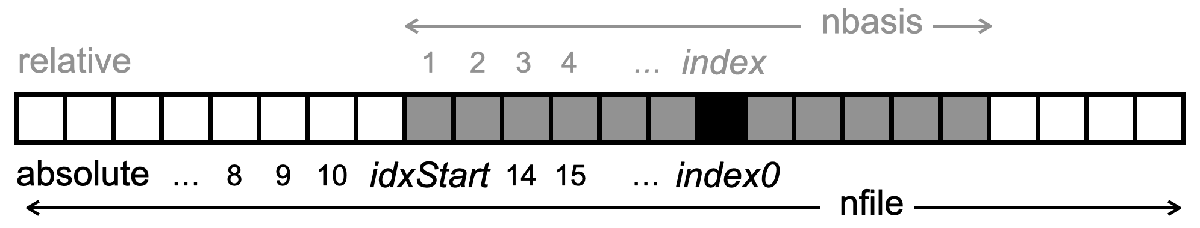

    if index0 < round(nbasis/2)                     % basis is composed of the nearest consecutive data for a given image.
        idxStart = 0;                               % for left few images, counting from the leftmost.
        index = index0;                             % (relative) index of the current processed image in a seleted basis.
    else
        if index0+round(nbasis/2)>nfile
            idxStart = nfile - nbasis;              % for right few images, counting to the rightmost.
            index = -nfile + index0 + nbasis;
        else
            idxStart = index0 - round(nbasis/2);    % for the other images, selecting equal left and right neighbours.
            index = round(nbasis/2);
        end
    end

            Import images and basis extension

             -*imgWOSet*  : reference image set composed of images **w**ith**o**ut atoms.

             -*imgWSet*  :   absorption image set composed of images **w**ith atoms

             -*imgBGSet*  : dark image set composed of images of **b**ack**g**round photons and camera noise (dark current and readout noise)

    shiftMax = 1;               % shift d, determined by the rank of data
    edge = 10;                  % cut edge for shifting images, should be >= shiftMax
    if idxStart ~= idxStartOld  % use a similar queue data stucture to store/import data sets efficiently
        if isnan(idxStartOld)   % first time to import image sets.
            nbasisRead = nbasis;
            idxStartRead = idxStart;
            [imgWOSet,imgWSet,imgBGSet,imgHeight,imgWidth] = Read_Bin(BinFolder,nbasisRead,idxStartRead,imgHeightRaw,imgWidthRaw, shiftMax, edge);
        else                    % calculate the basis difference, and load only differential images of the last and present basis.
            idxDiff = idxStart - idxStartOld;
            nbasisRead = abs(idxDiff); 
            if idxDiff>0        % if the index is in front of the last processed image, new images datasets will left push last data sets. 
                idxStartRead = idxStartOld + nbasis;
                [imgWOSetPush,imgWSetPush,imgBGSetPush] = Read_Bin(BinFolder,nbasisRead,idxStartRead,imgHeightRaw,imgWidthRaw, shiftMax, edge);
                imgWOSet = [imgWOSet(idxDiff*(2*shiftMax+1)^2+1:end,:,:);imgWOSetPush];
                imgWSet = [imgWSet(idxDiff+1:end,:,:);imgWSetPush];
                imgBGSet = [imgBGSet(idxDiff+1:end,:,:);imgBGSetPush];
            else                % if the index is behind the last processed image, new images datasets will right push last data sets.
                idxStartRead = idxStart;
                [imgWOSetPush,imgWSetPush,imgBGSetPush] = Read_Bin(BinFolder,nbasisRead,idxStartRead,imgHeightRaw,imgWidthRaw, shiftMax, edge);
                imgWOSet = [imgWOSetPush;imgWOSet(1:(nbasis+idxDiff)*(2*shiftMax+1)^2,:,:)];
                imgWSet = [imgWSetPush;imgWSet(1:(nbasis+idxDiff),:,:)];
                imgBGSet = [imgBGSetPush;imgBGSet(1:(nbasis+idxDiff),:,:)];            
            end
        end
    end
    idxStartOld = idxStart;    % update the old index.

            Mask the regime containing atoms

                                                                                   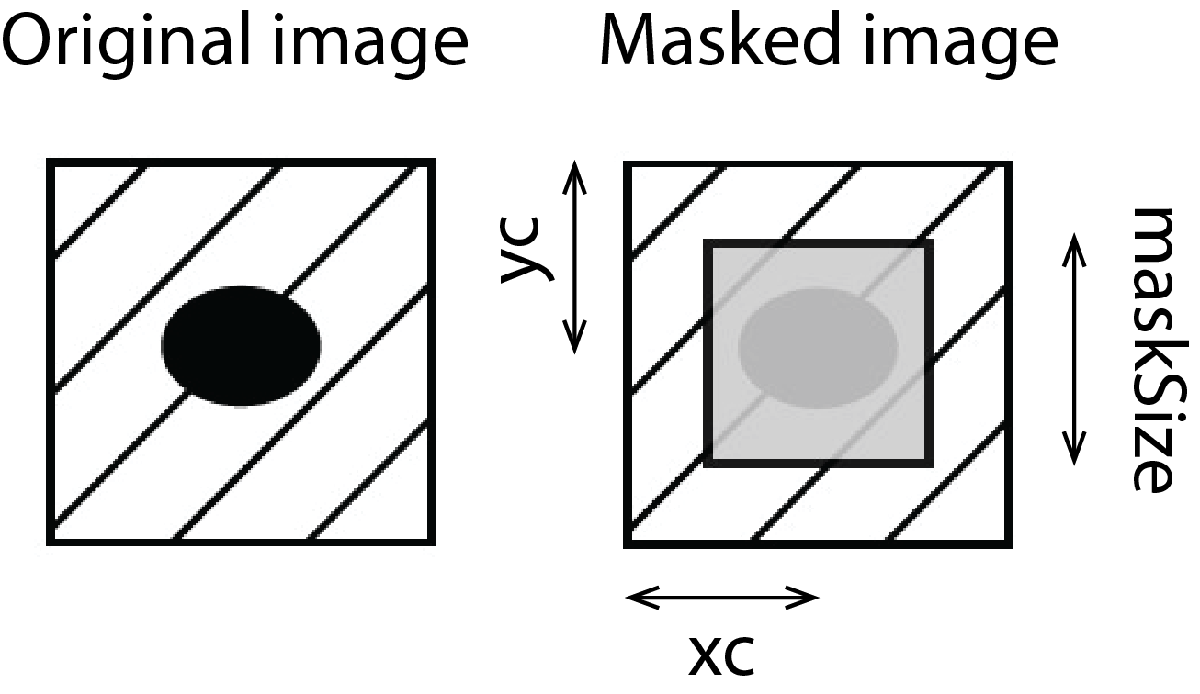

    xc = 100;            % x position of mask
    yc = 100;            % y position of mask
    maskSize = 100;      % mask size
    xw = maskSize/2;     % noted that the mask can be any shape/pattern covering the regime containing atoms.
    yw = maskSize/2;     % Here we simply choose a square.
    mask = ones(imgHeight, imgWidth);  % mask. 1 is unmasked while 0 is masked.
    mask(yc-yw:yc+yw,xc-xw:xc+xw) = 0;

###          Reconstruct the correct reference image

           (*index0 for whole dataset, index for selected basis)*

    imgWOSet2D = reshape(imgWOSet, nbasis*(2*shiftMax+1)^2, imgHeight*imgWidth);
    imgWOSet2Dmask = imgWOSet(:,boolean(mask));    % masked reference image set  

            Autocorrelation matrix *C*

                                
$$C_{j,k} = \Sigma_{x,y}\ \tilde{I}_j^{wo,e}(x,y)\cdot \tilde{I}_k^{wo,e}(x,y)$$


    C = imgWOSet2Dmask*imgWOSet2Dmask';
    WI = squeeze(imgWSet(index,:,:));
    imgWidx2D =  reshape(WI, 1, imgHeight*imgWidth);
    imgWidx2Dmask = WI(boolean(mask));             % masked absorption image set

            Projection matrix *P*

                                
$$P_{k} = \Sigma_{x,y}\  \tilde{I}^{w}(x,y)\cdot \tilde{I}_k^{wo,e}(x,y)$$


    P =imgWOSet2Dmask*imgWidx2Dmask;

            Coefficients of projection *β*

                                
$$P = \beta \times C$$


    beta = bicgstab(C, P, 1E-14);                 % Here prcision is set to 1E-14. bicgstab is an alternative to C\P

            Reconstruct the corrected reference image

                                
$$I^{wo,c} = \Sigma_j\  \beta_j I_j^{wo,e}$$


    imgWOidx2DNew = beta'*imgWOSet2D;toc;         % corrected ref img and time cost starting from tic.                              

###          Calcualte and compare the corrected and orginal OD

           Calculate the new OD

    WONew = reshape(imgWOidx2DNew, imgHeight, imgWidth);
    realidx = (index-1)*(2*shiftMax+1)^2 + 2*(shiftMax^2+shiftMax)+1;    % index in the extended basis.
    WO = squeeze(imgWOSet(realidx,:,:));
    BG = squeeze(imgBGSet(index,:,:));
    OD = log((WONew-BG)./(WI-BG));                % corrected OD. Noted please add contrains if the term in ln is Inf/NaN/negative.

           Comparison of old OD and new OD.

    hfig = figure('visible','off');               % draw the orginal and corrected OD, and save it.
    subplot(1,2,1);
    ODorg = log((WO-BG)./(WI-BG));                % original (uncorrected) OD image. Either read or recalcualte it.                                                 
    imagesc(ODorg,[0,0.05]);                      % set the range of colorbar                 
    daspect([1, 1, 1]);
    axis off;colorbar;title('Orginal OD');
    subplot(1,2,2);
    imagesc(OD,[0,0.05]);           
    daspect([1, 1, 1]);
    axis off;colorbar;title('Corrected OD');      % show the new and original OD image.
    Diff_old = sum(sum(abs(WI-WO).*mask))/sum(sum((WI+WO).*mask/2));  % normalized difference between WI and WO
    Diff_new = sum(sum(abs(WI-WONew).*mask))/sum(sum((WI+WONew).*mask/2));
    fprintf('Orginal diff \t%f and Corrected diff \t%f\n', Diff_old, Diff_new);         

           Save the result

    Diff(ilist,1) = Diff_old;
    Diff(ilist,2) = Diff_new;
    [~,fileStr,fileExt] = fileparts(filelistWO(index0).name);         % seperate file name
    writematrix(WONew,[ResultFolder,fs,'NewWO',fs,fileStr(1:end-2),'WO.bin'],'FileType',"text");
    writematrix(OD,[ResultFolder,fs,'NewOD',fs,fileStr(1:end-2),'OD.bin'],'FileType',"text");
    set(hfig, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);     % draw the image in the full size.
    saveas(hfig, [ResultFolder,fs,'CmpImg',fs,fileStr(1:end-2),'.png']);
    SumODorg = SumODorg + ODorg;
    SumOD = SumOD + OD;
    delete(hfig);
end

#1 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 1.4e-07.


Elapsed time is 0.267660 seconds.


Orginal diff 	0.024266 and Corrected diff 	0.012366


#2 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 1e-07.


Elapsed time is 0.045094 seconds.


Orginal diff 	0.016233 and Corrected diff 	0.011411


#3 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 9.1e-08.


Elapsed time is 0.046376 seconds.


Orginal diff 	0.021192 and Corrected diff 	0.011689


#4 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 9.4e-08.


Elapsed time is 0.042729 seconds.


Orginal diff 	0.017163 and Corrected diff 	0.011150


#5 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 1e-07.


Elapsed time is 0.043606 seconds.


Orginal diff 	0.024052 and Corrected diff 	0.011493


#6 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 6e-08.


Elapsed time is 0.038873 seconds.


Orginal diff 	0.015018 and Corrected diff 	0.011001


#7 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 1.5e-07.


Elapsed time is 0.049104 seconds.


Orginal diff 	0.016848 and Corrected diff 	0.011335


#8 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 1.6e-07.


Elapsed time is 0.050106 seconds.


Orginal diff 	0.015876 and Corrected diff 	0.011425


#9 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 5.7e-08.


Elapsed time is 0.040247 seconds.


Orginal diff 	0.015275 and Corrected diff 	0.011127


#10 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 1.6e-07.


Elapsed time is 0.042837 seconds.


Orginal diff 	0.017304 and Corrected diff 	0.010979


#11 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 8.1e-08.


Elapsed time is 0.167968 seconds.


Orginal diff 	0.014938 and Corrected diff 	0.010961


#12 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.8e-08.


Elapsed time is 0.157574 seconds.


Orginal diff 	0.016616 and Corrected diff 	0.010997


#13 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.9e-08.


Elapsed time is 0.155972 seconds.


Orginal diff 	0.015595 and Corrected diff 	0.010902


#14 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.7e-08.


Elapsed time is 0.151234 seconds.


Orginal diff 	0.014898 and Corrected diff 	0.010812


#15 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 1.3e-07.


Elapsed time is 0.153377 seconds.


Orginal diff 	0.016366 and Corrected diff 	0.011069


#16 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 4.5e-08.


Elapsed time is 0.155549 seconds.


Orginal diff 	0.015143 and Corrected diff 	0.010865


#17 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 4.3e-08.


Elapsed time is 0.152896 seconds.


Orginal diff 	0.014913 and Corrected diff 	0.010899


#18 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 4.2e-08.


Elapsed time is 0.159876 seconds.


Orginal diff 	0.018751 and Corrected diff 	0.010749


#19 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 7.3e-08.


Elapsed time is 0.153221 seconds.


Orginal diff 	0.021048 and Corrected diff 	0.011214


#20 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 1.6e-08.


Elapsed time is 0.156273 seconds.


Orginal diff 	0.015578 and Corrected diff 	0.011096


#21 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.5e-08.


Elapsed time is 0.160888 seconds.


Orginal diff 	0.016941 and Corrected diff 	0.011292


#22 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.5e-08.


Elapsed time is 0.161692 seconds.


Orginal diff 	0.015373 and Corrected diff 	0.010963


#23 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 1.8e-08.


Elapsed time is 0.156065 seconds.


Orginal diff 	0.018289 and Corrected diff 	0.010917


#24 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 1.3e-08.


Elapsed time is 0.287926 seconds.


Orginal diff 	0.015150 and Corrected diff 	0.010895


#25 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 6.4e-08.


Elapsed time is 0.040822 seconds.


Orginal diff 	0.018737 and Corrected diff 	0.011161


#26 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 3.8e-08.


Elapsed time is 0.043030 seconds.


Orginal diff 	0.019621 and Corrected diff 	0.011269


#27 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 3.2e-08.


Elapsed time is 0.048723 seconds.


Orginal diff 	0.015193 and Corrected diff 	0.010960


#28 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 2.1e-08.


Elapsed time is 0.047243 seconds.


Orginal diff 	0.018504 and Corrected diff 	0.011064


#29 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 19) has relative residual 2.7e-08.


Elapsed time is 0.068880 seconds.


Orginal diff 	0.015642 and Corrected diff 	0.011037


#30 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.4e-08.


Elapsed time is 0.044535 seconds.


Orginal diff 	0.016745 and Corrected diff 	0.011015


#31 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.7e-08.


Elapsed time is 0.043236 seconds.


Orginal diff 	0.014977 and Corrected diff 	0.010834


#32 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 3.3e-08.


Elapsed time is 0.039524 seconds.


Orginal diff 	0.017066 and Corrected diff 	0.010889


#33 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 4.7e-08.


Elapsed time is 0.042942 seconds.


Orginal diff 	0.018202 and Corrected diff 	0.011264


#34 


bicgstab stopped at iteration 20 without converging to the desired tolerance 1e-14
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 2.6e-08.


Elapsed time is 0.040230 seconds.


Orginal diff 	0.017062 and Corrected diff 	0.011304


## Results and Output

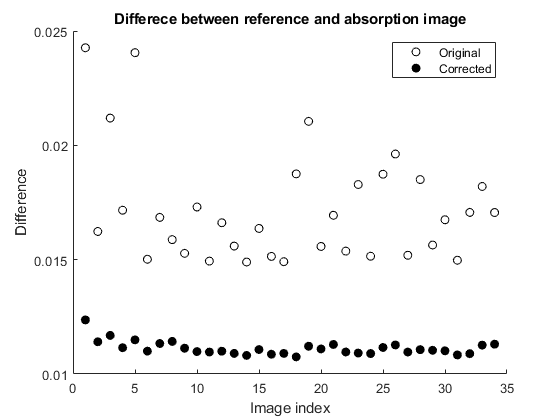

xlswrite([ResultFolder,fs,'CmpResult.xlsx'],[imgListFM', Diff]);       % save the difference into an excel file.
figure(100);clf; hold on;
plot(imgListFM, Diff(:,1),'ko')
plot(imgListFM, Diff(:,2),'ko','MarkerFaceColor','k'); 
legend('Original','Corrected');
title('Differece between reference and absorption image');
xlabel('Image index'); 
ylabel('Difference'); hold off;                                      

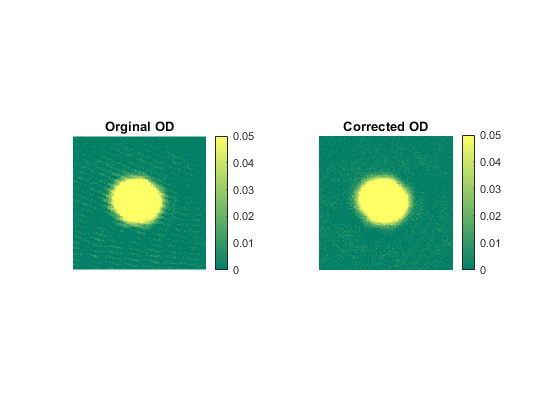


figure(101);clf;              % draw average OD images.
AvgODorg = SumODorg/nimgFM;   % average orginal OD
AvgOD = SumOD/nimgFM;         % average corrected OD
subplot(1,2,1);
imagesc(AvgODorg,[0,0.05]);   % set the range of colorbar
daspect([1, 1, 1]);           % set aspect ratio to 1
axis off; colorbar;
title('Orginal OD');
subplot(1,2,2);
imagesc(AvgOD,[0,0.05]);
daspect([1, 1, 1]); axis off; colorbar;
title('Corrected OD');
colormap(summer);

writematrix(AvgOD, [ResultFolder,fs,'AvgOD',fs,'NewOD.data'],'FileType',"text");    % write the average OD image.
writematrix(AvgODorg, [ResultFolder,fs,'AvgOD',fs,'OldOD.data'],'FileType',"text");    

## Function Pool

function [imgHeight,imgWidth] = Txt2Bin(original_folder,target_folder)
% Convert images to basic binary files.
%
% Input:
%   original_folder: Txt or Tif folder.
%   target_folder: Bin folder.
% Output:
%   imgHeight: height of image
%   imgWidth: width of image

sub_folder={'W','WO','BG'};
fs = filesep;      % file separator for current platform
for n = 1:length(sub_folder)
    fileFolder=[original_folder,fs,sub_folder{n}];
    dirOutput=dir(fileFolder);
    filelist={dirOutput.name}';
    filelist(1:2) = [];
    nfile=length(filelist);
    for k = 1:nfile
        filename = filelist{k};
        [~,fileStr,fileExt] = fileparts(filename);        % get parts of file name
        if strcmp(fileExt,'.tif')                         % if file is .tif
            img = double(imread([fileFolder,fs,filename]));
        else 
            if strcmp(fileExt,'.data')                    % if file is .data which is txt
            img = readmatrix([fileFolder,fs,filename],'FileType',"text");
            end
        end
        [imgHeight,imgWidth] = size(img);
        binFileName = [fileStr,sub_folder{n},'.bin'];  
        fileID = fopen([target_folder,fs,binFileName],'w');
        fwrite(fileID,img,'double');
        fclose(fileID);
    end
end
end


function [imgWOSet,imgWSet,imgBGSet,imgHeight,imgWidth] = Read_Bin(filedir,nbasis,idxStart,imgHeightRaw,imgWidthRaw, shiftMax, edge)
% Export absorption(W), extended reference(WO) and dark(BG) images
%
% Input:
%   filedir:  Bin folder.
%   nbasis:   the size of the basis.
%   idxStart: the start index of the basis.
%
% Output: 
%   imgWOSet: reference images (WO) set
%   imgWSet:  absorption images (W) set
%   imgBGSet: dark images (background images, BG) set
%   imgHeight:image height.
%   imgWidth: image width.
%   shiftMax: maximum shift.

fs = filesep;                              % file separator for current platform
filelistWO = dir([filedir,fs,'*WO.bin']);
filelistW = dir([filedir,fs,'*W.bin']);
filelistBG = dir([filedir,fs,'*BG.bin']);

imgHeight= imgHeightRaw-2*edge;            % size of images with cutting edges
imgWidth = imgWidthRaw-2*edge;

imgWOSet = zeros(nbasis*(2*shiftMax+1)^2, imgHeight, imgWidth);
imgWSet = zeros(nbasis, imgHeight, imgWidth);
imgBGSet = zeros(nbasis, imgHeight, imgWidth);

for i =1:nbasis
    fileidx = filelistWO(i+idxStart);      % read reference (WO) image set
    fileName = fileidx.name;
    fileFolder = fileidx.folder;
    
    fileID = fopen([fileFolder,fs,fileName]);  % read Bin data
    img0 = fread(fileID, [imgHeightRaw, imgWidthRaw], 'double');
    fclose(fileID);                            % close reading
    
    iidx = 0;
    for j = -shiftMax:shiftMax
        for k = -shiftMax:shiftMax
            iidx = iidx+1;
            img = circshift(circshift(img0, j, 1), k, 2);  % shift images in basis
            imgWOSet((i-1)*(2*shiftMax+1)^2+iidx,:,:) = img(edge+1:end-edge,edge+1:end-edge); % cut image edges.
        end
    end
    
    fileidx = filelistW(i+idxStart);       % read absorption (W) image set
    fileName = fileidx.name;
    fileFolder = fileidx.folder;
    fileID = fopen([fileFolder,fs,fileName]);
    img = fread(fileID, [imgHeightRaw, imgWidthRaw], 'double');
    fclose(fileID);
    imgWSet(i,:,:) = img(edge+1:end-edge,edge+1:end-edge);
    
    fileidx = filelistBG(i+idxStart);      % read dark (BG) image set
    fileName = fileidx.name;
    fileFolder = fileidx.folder;
    fileID = fopen([fileFolder,fs,fileName]);
    img = fread(fileID, [imgHeightRaw, imgWidthRaw], 'double');
    fclose(fileID);
    imgBGSet(i,:,:) = img(edge+1:end-edge,edge+1:end-edge);
end
end